%Computes ionization cross section using 5
%1. define range of incident electron energy
me = 9.10938356E-31;
c = 3e8;
e = 1.6021766208e-19;
a0 = 5.2917721054482e-11;
alpha = 1/137;
R = 13.6*e;
E1 = linspace(13,110,300)*e;
E2 = linspace(110 ,1e4, 1500)*e;
E = [E1, E2(2:end)];
E = linspace(12,4e3,1000);
E = E*e;%in J

%2. Orbital binding energy

% In sequence of inner orbit to outer
% Binding energy of each orbit from Kim 12 TABLE IV, in eV
B = [35755.82, 5509.33, 5161.43, 4835.57, 1170.37, 1024.78, 961.25, 708.13, 694.90, 229.39, 175.58, 162.8, 73.78, 71.67, 27.49, 13.40, 12.1298];
%B = [34561,5453,5107,4786,1148.7,1002.1,940.6,689,676.4,213.2,146.7,145.5,69.5,67.5,23.3,13.4,12.1];
% Mean kinetic energy of binding electron, in eV
U = [42281.58, 9173.91, 9135.67, 8324.23, 2722.32, 2642.38, 2453.45, 2311.18, 2261.96, 757.48, 690.54, 643.34, 497.77, 485.43, 122.58, 88.90, 79.42];
% Occupation number
N = [2, 2, 2, 4, 2, 2, 4, 4, 6, 2, 2, 4, 4, 6, 2, 2, 4];
% convert to J

B = B*e;
U = U*e;
B = flip(B);
U = flip(U);
N = flip(N);
orbital = ["5p3/2","5p1/2","5s1/2","4d5/2","4d3/2","4p3/2","4p1/2","4s1/2","3d5/2","3d3/2","3p3/2","3p1/2","3s1/2","2p3/2","2p1/2","2s1/2","1s1/2"];
%principle quantum number
n = 5;
ratios = [1/3, 2/3, 1, 3/5, 2/5, 2/3, 1/3, 1, 3/5, 2/5, 2/3, 1/3, 1, 2/3, 1/3, 1, 1];


%3. calculate cross section of kth orbital, using 22.Kim
sigma_BEB = zeros(size(E));

for i = 1:length(E)
    T = E(i);
    BEB_per_orbital = zeros(1,length(B));
    
    for j = 1:17
        S = 4*pi*a0^2*N(j)*(R/B(j))^2;
        t = T./B(j);
        u = U(j)./B(j);
        BEB_per_orbital(j) = S/(t+(u+1)/n)*(log(t)/2*(1-1/t^2) +1 - 1/t - log(t)/(t+1)  );
    end
    %sigma_BEB(i) = BEB_per_orbital(3)*2 + (BEB_per_orbital(4) + BEB_per_orbital(5))*3 + (BEB_per_orbital(6) + BEB_per_orbital(7) + BEB_per_orbital(8))*4;
    sigma_BEB(i) = sum(BEB_per_orbital(1:3));
end

%Experimental data
E1 = [140 160 180 200 225 250 300 350 400 450 500 550 600 650 700 750 800 850 900 950 1000 1100 1200 1300 1400 1500 1600 1700 1800 1900 2000 2500 3000 3500 4000];
sigma1 = [445.5,422.5,401.9,383.0,361.3,342.7,311.5,286.7,265.7,247.9,231.2,217.9,205.8,194.9,184.9,176.0,168.1,161.2,154.9,149.2,143.7,134.1,125.8,118.5,112.0,106.5,101.6,96.8,92.6,88.7,85.3,71.9,62.26,55.14,49.72];
sigma1 = sigma1*1e6*1e-28;
E2 = [15.0, 20.0, 25.0, 30.0, 35.0, 40.0, 45.0, 50.0,55.0, 60.0, 65.0, 70.0, 75.0, 80.0, 85.0, 90.0, 95.0, 100.0, 105.0, 110.0, 115.0, 120.0, 125.0,130.0, 135.0, 140.0, 145.0, 150.0, 155.0, 160.0, 165.0, 170.0, 175.0, 180.0];
sigma2 = [1.15e-20, 2.42e-20, 3.81e-20, 4.17e-20, 4.17e-20,4.30e-20, 4.31e-20, 4.29e-20, 4.27e-20, 4.37e-20, 4.47e-20, 4.54e-20,4.57e-20, 4.59e-20, 4.55e-20, 4.48e-20, 4.42e-20, 4.31e-20, 4.26e-20, 4.21e-20, 4.13e-20, 4.06e-20, 3.99e-20, 3.97e-20, 3.92e-20,3.87e-20, 3.85e-20, 3.82e-20, 3.78e-20, 3.74e-20, 3.73e-20, 3.67e-20, 3.63e-20, 3.58e-20];
E31 = 12:1:40;
E32 = 45:5:200;
E3 = [E31 E32];
sigma31 = [0.1 0.31 0.63 1.0 1.35 1.65 1.93 2.17 2.42 2.67 2.91 3.12 3.3 3.46 3.59 3.73 3.89 4.04 4.13 4.23 4.33 4.43 4.51 4.59 4.62 4.67 4.72 4.74 4.8 4.82 4.84 4.86 4.89 4.93 4.96 4.98 4.95 4.95 4.92 4.88 4.84 4.78 4.77 4.69 4.63 4.59 4.55 4.5 4.46 4.44 4.38 4.33 4.3 4.26 4.24 4.19 4.16 4.12 4.08 4.05 4.03]

sigma31 =     0.1000    0.3100    0.6300    1.0000    1.3500    1.6500    1.9300    2.1700    2.4200    2.6700    2.9100    3.1200    3.3000    3.4600    3.5900    3.7300    3.8900    4.0400    4.1300    4.2300    4.3300    4.4300    4.5100    4.5900    4.6200    4.6700    4.7200    4.7400    4.8000    4.8200    4.8400    4.8600    4.8900    4.9300    4.9600    4.9800    4.9500    4.9500    4.9200    4.8800    4.8400    4.7800    4.7700    4.6900    4.6300    4.5900    4.5500    4.5000    4.4600    4.4400


sigma32 = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.002 0.004 0.001 0.008 0.016 0.016 0.034 0.046 0.065 0.157 0.26 0.323 0.363 0.377 0.389 0.4 0.411 0.436 0.456 0.482 0.51 0.531 0.545 0.552 0.553 0.552 0.542 0.534 0.525 0.504 0.494 0.477 0.467 0.458 0.446 0.434 0.426 0.413 0.406 0.394 0.391]

sigma32 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0020    0.0040    0.0010    0.0080    0.0160    0.0160    0.0340    0.0460    0.0650    0.1570    0.2600    0.3230    0.3630    0.3770    0.3890    0.4000    0.4110    0.4360    0.4560    0.4820    0.5100    0.5310    0.5450    0.5520    0.5530    0.5520    0.5420    0.5340    0.5250    0.5040


sigma33 = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.003 0.004 0.009 0.021 0.033 0.047 0.065 0.087 0.109 0.129 0.147 0.164 0.174 0.178 0.182 0.186 0.186 0.180 0.179 0.175 0.170 0.169 0.166 0.162 0.160 0.155 0.156]

sigma33 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0030    0.0040    0.0090    0.0210    0.0330    0.0470    0.0650    0.0870    0.1090    0.1290    0.1470    0.1640    0.1740    0.1780    0.1820    0.1860


sigma3 = (sigma33+sigma32+sigma31)*1e-20;



%5. Cross section using PIC.8
sigma_RBEB = zeros(size(E));
for i = 1:length(E)
    T = E(i);
    RBEB_per_orbital = zeros(1,length(B));
    for j = 1:17
        t = T./B(j);
        u = U(j)./B(j);
        
        tp = T/me/c^2;
        bp = B(j)/me/c^2;
        up = U(j)/me/c^2;
        
        Bt2 = 1 - 1./(1+tp).^2;
        Bb2 = 1 - 1./(1+bp).^2;
        Bu2 = 1 - 1./(1+up).^2;
       
        anl = 1/2*(1 + (Bt2 + Bu2 + Bb2)./Bt2);
        bnl = 2*pi*a0^2*alpha^4/(Bt2 + Bu2 + Bb2)./bp*N(j);%of each electron
        cnl = 1/2*(log(Bt2./(1-Bt2)) - Bt2 - log(2*bp));
        dnl = 1- 1./t - log(t)./(t+1).*(1+2.*tp)./(1+tp/2).^2 + bp.^2.*(t-1)./(1 + tp/2).^2 ./2;
        RBEB_per_orbital(j) = anl*bnl*(cnl*(1-1/t^2) + dnl);
    end
    sigma_RBEB(i) = sum(RBEB_per_orbital(1:3));
end


% Energy transferred using 8
%eqn.16 and 17
function F = F_function(eps_delta, sigma_r, a_nl, b_nl, c_nl, w, t, tp, bp)
    % F_function calculates the distribution function F(eps_delta)
    % based on the literature equations.
    %
    % Inputs:
    % - eps_delta: Energy transferred to the secondary electron (array or scalar)
    % - sigma_r: Reference cross-section (scalar)
    % - a_nl, b_nl, c_nl: Constants for each nl shell (arrays of same length)
    % - w: Energy parameter in literature (scalar)
    % - t: Energy parameter in literature (scalar)
    % - bp: Another constant related to b' (scalar)
    %
    % Output:
    % - F: The value of F(eps_delta)

    % Initialize the output F
    F = zeros(size(eps_delta));

    % Loop over all nl shells and sum the contributions to F(eps_delta)
    for i = 1:length(a_nl)
        % Unpack constants for the nl shell
        an = a_nl(i);
        bn = b_nl(i);
        cn = c_nl(i);

        % Equation (17) terms for the single shell contribution
        term1 = (1 / (t - w)^2) - (1 / (w + 1)^2) - 1 / (t^2 + 1);
        term2 = (1 / (t - w)) * (1 / (w + 1 + 1)) + (1 / t);
        term3 = (bp^2 * w) / (1 + 0.5 * tp)^2;
        term4 = -log( (t * (w + 1)) / (t - w) ) * 1 / (1 + t) * (1 + 2 * tp) / (1 + 0.5 * tp)^2;

        % Contribution from this nl shell
        sigma_nl_contrib = an * bn * (term1 * cn + term2 + term3 + term4);

        % Integrate over eps_delta for this shell (numerical integration approximation)
        F = F + (sigma_nl_contrib / sigma_r) * eps_delta;  % Sum contributions
    end
end

t = T./B(j);
u = U(j)./B(j);
tp = T/me/c^2;
bp = B(j)/me/c^2;


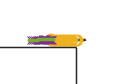

%plot with experimental data
figure;
figure(1)
clf;
plot(E/e,sigma_BEB)
hold on
plot(E/e,sigma_RBEB)
hold on
scatter(E1, sigma1)
hold on
scatter(E2, sigma2,'x')
hold on
scatter(E3,sigma3,'.')
set(gca, 'XScale', 'log'); % Set x-axis to logarithmic scale
set(gca, 'fontsize', 18)
legend("BEB 22","RBEB 8","Experiment K. Stephan","Experiment A. A. Sorokin",'R.C. Wetzel')

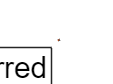

figure(2)
clf;
plot(E/e,w_bar/e)
hold on
plot(E/e,e_bar/e)
legend("Energy transferred", "Energy lost")
ylabel("eV")
xlabel("eV")
set(gca, 'XScale', 'log'); % Set x-axis to logarithmic scale
set(gca, 'fontsize', 18)

%Save to matrixes
writematrix(E/e, 'Tnew.csv');
writematrix(sigma_BEB,'sigmanew.csv')
writematrix(w_bar,'Wnew.csv')
writematrix(e_bar,'Enew.csv')